# Modulation Classification with Deep Learning

This example shows how to use a convolutional neural network (CNN) for modulation classification. You generate synthetic, channel-impaired waveforms. Using the generated waveforms as training data, you train a CNN for modulation classification. You then test the CNN with software-defined radio (SDR) hardware and over-the-air signals.

## Predict Modulation Type Using CNN

The trained CNN in this example recognizes these eight digital and three analog modulation types: 

- Binary phase shift keying (BPSK)

- Quadrature phase shift keying (QPSK)

- 8-ary phase shift keying (8-PSK)

- 16-ary quadrature amplitude modulation (16-QAM)

- 64-ary quadrature amplitude modulation (64-QAM)

- 4-ary pulse amplitude modulation (PAM4)

- Gaussian frequency shift keying (GFSK)

- Continuous phase frequency shift keying (CPFSK)

- Broadcast FM (B-FM)

- Double sideband amplitude modulation (DSB-AM)

- Single sideband amplitude modulation (SSB-AM)

modulationTypes = categorical(["BPSK", "QPSK", "8PSK", ...
  "16QAM", "64QAM", "PAM4", "GFSK", "CPFSK", ...
  "B-FM", "DSB-AM", "SSB-AM"]);

% modulationTypes = categorical(["BPSK", "QPSK",  ...
%   "16QAM", "PAM4", "GFSK", "CPFSK", ...
%   "B-FM", "DSB-AM", "SSB-AM"]);

First, load the trained network. For details on network training, see the Training a CNN section.

load trainedModulationClassificationNetwork
trainedNet

trainedNet =   SeriesNetwork with properties:

         Layers: [28×1 nnet.cnn.layer.Layer]
     InputNames: {'Input Layer'}
    OutputNames: {'Output'}


The trained CNN takes 1024 channel-impaired samples and predicts the modulation type of each frame. Generate several PAM4 frames that are impaired with Rician multipath fading, center frequency and sampling time drift, and AWGN. Use following function  to generate synthetic signals to test the CNN. Then use the CNN to predict the modulation type of the frames.

- [randi](docid:matlab_ref#buf2csg):  Generate random bits

- [pammod:](docid:comm_ref#a1042480014b1) PAM4-modulate the bits

- [rcosdesign](docid:signal_ref#bt00vcn): Design a square-root raised cosine pulse shaping filter

- [filter](docid:matlab_ref#bt_vs4t-1): Pulse shape the symbols

- [comm.RicianChannel](docid:comm_ref#btzx8bh-1): Apply Rician multipath channel

- [comm.PhaseFrequencyOffset](docid:comm_ref#bsnfizs_4): Apply phase and/or frequency shift due to clock offset

- [interp1](docid:matlab_ref#btwp6lt-1): Apply timing drift due to clock offset

- [awgn](docid:comm_ref#fp1221678): Add AWGN

% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(123456)
% Random bits
d = randi([0 3], 1024, 1);
% PAM4 modulation
syms = pammod(d,4);
% Square-root raised cosine filter
filterCoeffs = rcosdesign(0.35,4,8);
tx = filter(filterCoeffs,1,upsample(syms,8));

% Channel
SNR = 30;
maxOffset = 5;
fc = 902e6;
fs = 200e3;
multipathChannel = comm.RicianChannel(...
  'SampleRate', fs, ...
  'PathDelays', [0 1.8 3.4] / 200e3, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4);

frequencyShifter = comm.PhaseFrequencyOffset(...
  'SampleRate', fs);

% Apply an independent multipath channel
reset(multipathChannel)
outMultipathChan = multipathChannel(tx);

% Determine clock offset factor
clockOffset = (rand() * 2*maxOffset) - maxOffset;
C = 1 + clockOffset / 1e6;

% Add frequency offset
frequencyShifter.FrequencyOffset = -(C-1)*fc;
outFreqShifter = frequencyShifter(outMultipathChan);

% Add sampling time drift
t = (0:length(tx)-1)' / fs;
newFs = fs * C;
tp = (0:length(tx)-1)' / newFs;
outTimeDrift = interp1(t, outFreqShifter, tp);

% Add noise
rx = awgn(outTimeDrift,SNR,0);

% Frame generation for classification
unknownFrames = helperModClassGetNNFrames(rx);

% Classification
[prediction1,score1] = classify(trainedNet,unknownFrames);

Return the classifier predictions, which are analogous to hard decisions. The network correctly identifies the frames as PAM4 frames. For details on the generation of the modulated signals, see [helperModClassGetModulator](matlab:openExample('ModulationClassificationWithDeepLearningExample', 'supportingFile', 'helperModClassGetModulator')) function.

prediction1

prediction1 = 7×1 categorical array
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 


The classifier also returns a vector of scores for each frame.  The score corresponds to the probability that each frame has the predicted modulation type. Plot the scores.

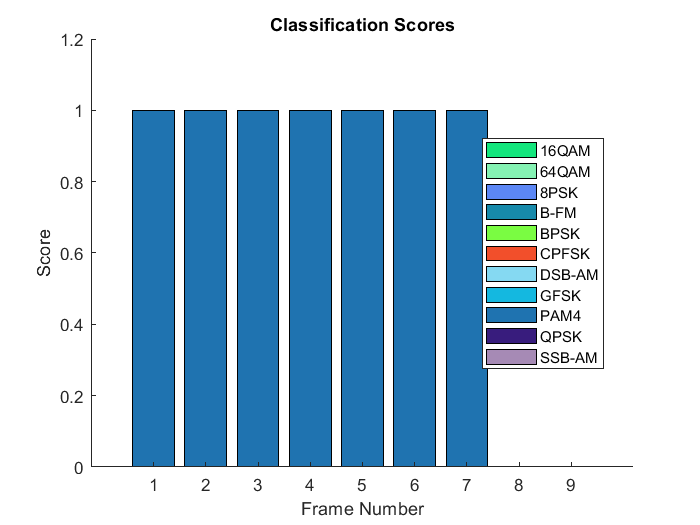

helperModClassPlotScores(score1,modulationTypes)

Before we can use a CNN for modulation classification, or any other task, we first need to train the network with known (or labeled) data. The first part of this example shows how to use Communications Toolbox features, such as modulators, filters, and channel impairments, to generate synthetic training data. The second part focuses on defining, training, and testing the CNN for the task of modulation classification. The third part tests the network performance with over-the-air signals using software defined radio (SDR) platforms.

## Waveform Generation for Training

Generate 10,000 frames for each modulation type, where 80% is used for training, 10% is used for validation and 10% is used for testing. We use training and validation frames during the network training phase. Final classification accuracy is obtained using test frames. Each frame is 1024 samples long and has a sample rate of 200 kHz. For digital modulation types, eight samples represent a symbol. The network makes each decision based on single frames rather than on multiple consecutive frames (as in video). Assume a center frequency of 902 MHz and 100 MHz for the digital and analog modulation types, respectively.

To run this example quickly, use the trained network and generate a small number of training frames. To train the network on your computer, choose the "Train network now" option (i.e. set trainNow to true).

trainNow = true;
if trainNow == true
  numFramesPerModType = 20000;
else
  numFramesPerModType = 10;
end
percentTrainingSamples = 80;
percentValidationSamples = 10;
percentTestSamples = 10;

sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
fs = 200e3;             % Sample rate
fc = [902e6 100e6];     % Center frequencies
%fc = [55e6 55e6]

### Create Channel Impairments

Pass each frame through a channel with

- AWGN

- Rician multipath fading

- Clock offset, resulting in center frequency offset and sampling time drift

Because the network in this example makes decisions based on single frames, each frame must pass through an independent channel. 

#### AWGN

The channel adds AWGN with an SNR of 30 dB. Implement the channel using [awgn](docid:comm_ref#fp1221678) function. 

#### Rician Multipath

The channel passes the signals through a Rician multipath fading channel using the [comm.RicianChannel](docid:comm_ref#btzx8bh-1) System object. Assume a delay profile of [0 1.8 3.4] samples with corresponding average path gains of [0 -2 -10] dB. The K-factor is 4 and the maximum Doppler shift is 4 Hz, which is equivalent to a walking speed at 902 MHz. Implement the channel with the following settings. 

#### Clock Offset

Clock offset occurs because of the inaccuracies of internal clock sources of transmitters and receivers. Clock offset causes the center frequency, which is used to downconvert the signal to baseband, and the digital-to-analog converter sampling rate to differ from the ideal values. The channel simulator uses the clock offset factor $C$, expressed as $C=1+\frac{\Delta_{\textrm{clock}} }{{10}^6 }$, where $\Delta_{\textrm{clock}}$ is the clock offset. For each frame, the channel generates a random $\Delta_{\textrm{clock}}$ value from a uniformly distributed set of values in the range [${-\max \Delta }_{\textrm{clock}}$ ${\max \Delta }_{\textrm{clock}}$], where ${\max \Delta }_{\textrm{clock}}$ is the maximum clock offset. Clock offset is measured in parts per million (ppm). For this example, assume a maximum clock offset of 5 ppm.

maxDeltaOff = 5;
deltaOff = (rand()*2*maxDeltaOff) - maxDeltaOff;
C = 1 + (deltaOff/1e6);

**Frequency Offset**

Subject each frame to a frequency offset based on clock offset factor $C$ and the center frequency. Implement the channel using [comm.PhaseFrequencyOffset](docid:comm_ref#bsnfizs_4).

**Sampling Rate Offset**

Subject each frame to a sampling rate offset based on clock offset factor $C$. Implement the channel using the [interp1](docid:matlab_ref#btwp6lt-1) function to resample the frame at the new rate of $C\times f_s$.

#### Combined Channel

Use the [helperModClassTestChannel](matlab:edit('helperModClassTestChannel.m')) object to apply all three channel impairments to the frames. 

channel = helperModClassTestChannel(...
  'SampleRate', fs, ...
  'SNR', SNR, ...
  'PathDelays', [0 1.8 3.4] / fs, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4, ...
  'MaximumClockOffset', 5, ...
  'CenterFrequency', 902e6)

channel =   helperModClassTestChannel with properties:

                    SNR: 30
        CenterFrequency: 902000000
             SampleRate: 200000
             PathDelays: [0 9.0000e-06 1.7000e-05]
       AveragePathGains: [0 -2 -10]
                KFactor: 4
    MaximumDopplerShift: 4
     MaximumClockOffset: 5


% channel = helperModClassTestChannel(...
%   'SampleRate', fs, ...
%   'SNR', SNR, ...
%   'PathDelays', [0 200 800 1200 2300 3700]*1e-9, ...
%   'AveragePathGains', [0 -0.9 -4.9 -8 -7.8 -23.9], ...
%   'KFactor', 4, ...
%   'MaximumDopplerShift', 50, ...
%   'MaximumClockOffset', 5, ...
%   'CenterFrequency', 902e6)

You can view basic information about the channel using the info object function.

chInfo = info(channel)

chInfo = struct with fields:
               ChannelDelay: 6
     MaximumFrequencyOffset: 4510
    MaximumSampleRateOffset: 1


### Waveform Generation

Create a loop that generates channel-impaired frames for each modulation type and stores the frames with their corresponding labels in MAT files. By saving the data into files, you eliminate the need to generate the data every time you run this example. You can also share the data more effectively. 

Remove a random number of samples from the beginning of each frame to remove transients and to make sure that the frames have a random starting point with respect to the symbol boundaries. 

% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(1235)
tic

numModulationTypes = length(modulationTypes);

channelInfo = info(channel);
transDelay = 50;
dataDirectory = fullfile(tempdir,"ModClassDataFiles");
disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\amitm\AppData\Local\Temp\ModClassDataFiles


fileNameRoot = "frame";

% Check if data files exist
dataFilesExist = false;
if exist(dataDirectory,'dir')
  files = dir(fullfile(dataDirectory,sprintf("%s*",fileNameRoot)));
  if length(files) == numModulationTypes*numFramesPerModType
    dataFilesExist = true;
  end
end

if ~dataFilesExist
  disp("Generating data and saving in data files...")
  [success,msg,msgID] = mkdir(dataDirectory);
  if ~success
    error(msgID,msg)
  end
 
  % initialize databases
  frame_matrix = zeros([numFramesPerModType*numModulationTypes,2*spf + 1 + 1]);
  frame_2C = zeros(2*spf + 1,numFramesPerModType*numModulationTypes);
%   frame_matrix = zeros([numFramesPerModType*numModulationTypes,spf + 1]);
  for modType = 1:numModulationTypes
    fprintf('%s - Generating %s frames\n', ...
      datestr(toc/86400,'HH:MM:SS'), modulationTypes(modType))
    
    label = modulationTypes(modType);
    numSymbols = (numFramesPerModType / sps);
    dataSrc = helperModClassGetSource(modulationTypes(modType), sps, 2*spf, fs);
    modulator = helperModClassGetModulator(modulationTypes(modType), sps, fs);
    if contains(char(modulationTypes(modType)), {'B-FM','DSB-AM','SSB-AM'})
      % Analog modulation types use a center frequency of 100 MHz
%       channel.CenterFrequency = 100e6;
      channel.CenterFrequency = 55e6;
    else
      % Digital modulation types use a center frequency of 902 MHz
%       channel.CenterFrequency = 902e6;
      channel.CenterFrequency = 55e6;
    end
    
    
    for p=1:numFramesPerModType
      
       channle.SNR = randi([0 30]);
        
      % Generate random data
      x = dataSrc();
      
      % Modulate
      y = modulator(x);
      
      % Pass through independent channels
%       rxSamples = channel(y);
      rxSamples = y;
      % Remove transients from the beginning, trim to size, and normalize
      frame = helperModClassFrameGenerator(rxSamples, spf, spf, transDelay, sps);
      % Save data file
%       fileName = fullfile(dataDirectory,...
%         sprintf("%s%s%03d",fileNameRoot,modulationTypes(modType),p));
%       save(fileName,"frame_lable")
%       writematrix(frame_lable,fileName)
%       frame_lable = [modType, modType ;real(frame), imag(frame)].';
      NormalizeFrame = false;
      if NormalizeFrame
            IQ_frame_Normalize = frame / max(abs(frame));
      end
      
      frame_complex = [real(IQ_frame_Normalize) , imag(IQ_frame_Normalize)];
      frame_shape = reshape(frame_complex.',1,[]);
      frame_matrix(p + (modType-1)*numFramesPerModType,:) = [modType, channle.SNR, frame_shape] ;
      
      frame_2C(:,p + (modType-1)*numFramesPerModType) = [modType; real(frame); imag(frame)];
    end
  end
else
  disp("Data files exist. Skip data generation.")
end

Generating data and saving in data files...


00:00:00 - Generating BPSK frames
00:00:05 - Generating QPSK frames
00:00:10 - Generating 8PSK frames
00:00:16 - Generating 16QAM frames
00:00:36 - Generating 64QAM frames
00:00:58 - Generating PAM4 frames
00:01:05 - Generating GFSK frames
00:01:15 - Generating CPFSK frames
00:01:23 - Generating B-FM frames
00:01:38 - Generating DSB-AM frames
00:01:50 - Generating SSB-AM frames


% save into csv file for python script
frame_matrix1 = zeros([numFramesPerModType*numModulationTypes/2, 2*spf + 1 + 1]);
frame_matrix2 = zeros([numFramesPerModType*numModulationTypes/2, 2*spf + 1 + 1]);

frame_matrix1 = frame_matrix(1:numFramesPerModType*numModulationTypes/2,:);
frame_matrix2 = frame_matrix(numFramesPerModType*numModulationTypes/2:end,:);

fileNameRoot1 = "frame11";
fileNameRoot2 = "frame22";
    fileName = fullfile(dataDirectory,...
        sprintf("%s",fileNameRoot1));
    writematrix(frame_matrix1,fileName)
    
    fileName = fullfile(dataDirectory,...
        sprintf("%s",fileNameRoot2));
    writematrix(frame_matrix2,fileName)
    
    disp('Done! (train data)')

Done! (train data)


    
% % save into csv file for c++ script
% fileName = fullfile(dataDirectory,...
%         sprintf("%s","Database_2C"));
%     writematrix(frame_2C,fileName)
%     disp('Done!')